clear

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

Nvar = 2;
Nmax = 50;
errodf = 15e-3;
NPontosIniciais = 7;
x_values=[-11;-11]; y_values=[7;7];
lambda = 0.0005;

PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar,x_values,y_values)

PontosIniciais =    -4.0769   -6.4675    0.1076    3.8388    2.1445   -0.4868    5.3135
   -0.5062   -5.7721   -6.2249    6.6879   -4.8102   -9.0602    4.8338



[Lista, LNit, Lopt] = steepest_descent_static_2(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda)

Lista =    -4.0769   -3.8759   -3.7041   -3.5554   -3.4252   -3.3102   -3.2078   -3.1159   -3.0332   -2.9581   -2.8899   -2.8275   -2.7703   -2.7176   -2.6690   -2.6241   -2.5824   -2.5437   -2.5077   -2.4740   -2.4426   -2.4132   -2.3856   -2.3598   -2.3355   -2.3126   -2.2911   -2.2708   -2.2516   -2.2335   -2.2164   -2.2002   -2.1849   -2.1704   -2.1567   -2.1437   -2.1313   -2.1195   -2.1084   -2.0978   -2.0877   -2.0781   -2.0689   -2.0602   -2.0520   -2.0441   -2.0366   -2.0294   -2.0225   -2.0160
   -0.5062   -0.5311   -0.5560   -0.5808   -0.6056   -0.6304   -0.6551   -0.6797   -0.7042   -0.7286   -0.7529   -0.7771   -0.8011   -0.8250   -0.8487   -0.8722   -0.8955   -0.9186   -0.9415   -0.9642   -0.9866   -1.0088   -1.0307   -1.0523   -1.0736   -1.0946   -1.1154   -1.1358   -1.1559   -1.1757   -1.1952   -1.2143   -1.2331   -1.2516   -1.2697   -1.2874   -1.3048   -1.3218   -1.3385   -1.3548   -1.3708   -1.3863   -1.4016   -1.4165   -1.4310   -1.4451   -1.4589   -1.4724   -1.4855 

LNit =     50    50    50    50    50    50    50


Lopt =    -2.0160   -2.0554   -1.0518    4.1057    2.8843   -1.4883    4.3230
   -1.4983   -2.0483   -2.0532    4.3930   -2.0336   -2.0686    4.2782


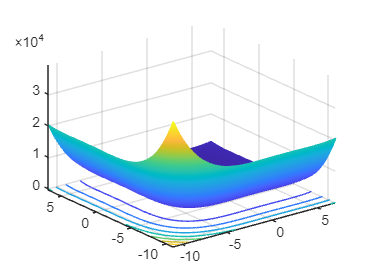

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

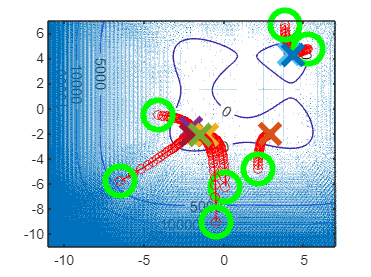


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off